clc; clear all; close all;

img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

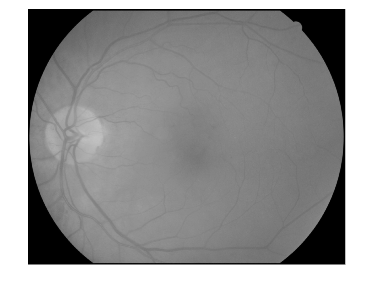

RGB = imread(string(fullfile(img_path, T{1,1})));%Aquí elijes la imagen
Ig=rgb2gray(RGB);
imshow(Ig);

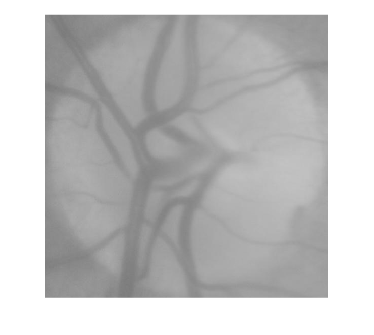

margen=280;
centroideY=1203;
centroideX=440;
Ig_r=Ig(centroideY-margen:centroideY+margen, centroideX-margen:centroideX+margen);
imshow(Ig_r);

Ig_r=double(Ig_r);
Ig_filtro=1./Ig_r;

Results=conv2(Ig,Ig_filtro);

imshow(Results,[]);

% Calcula la diferencia absoluta con el valor 1
diferencias = abs(Results - 1);

% Encuentra el valor mínimo y su índice lineal
[val_min, ind_lineal] = min(diferencias(:));

% Convierte el índice lineal a subíndices
[fila, columna] = ind2sub(size(Results), ind_lineal);

% Muestra las coordenadas del elemento más cercano a 1
fprintf('El elemento más cercano a 1 es %f y se encuentra en la fila %d, columna %d.\n', Results(fila, columna), fila, columna);

El elemento más cercano a 1 es 0.999992 y se encuentra en la fila 1103, columna 9.


El valor máximo es 3.207711e+05 y se encuentra en la fila 1486, columna 816.


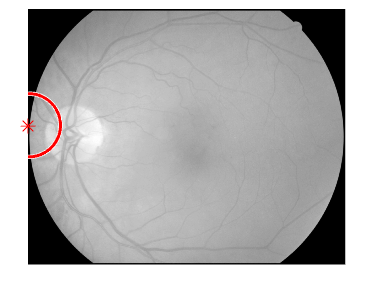

figure;
imshow(Ig,[]);
hold on
plot(columna, fila, 'r*', 'MarkerSize', 10);
viscircles([columna, fila],300);
hold off